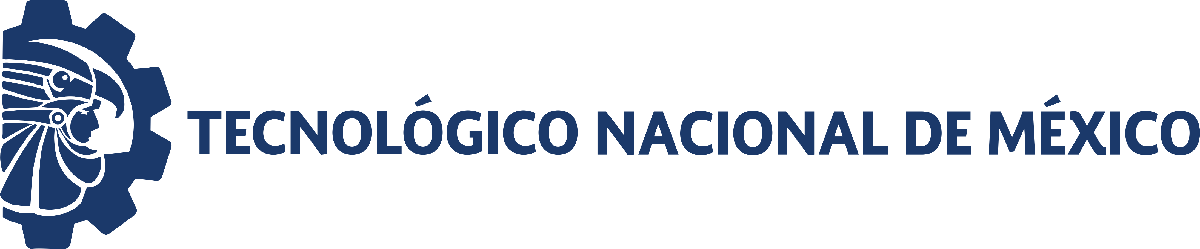                                 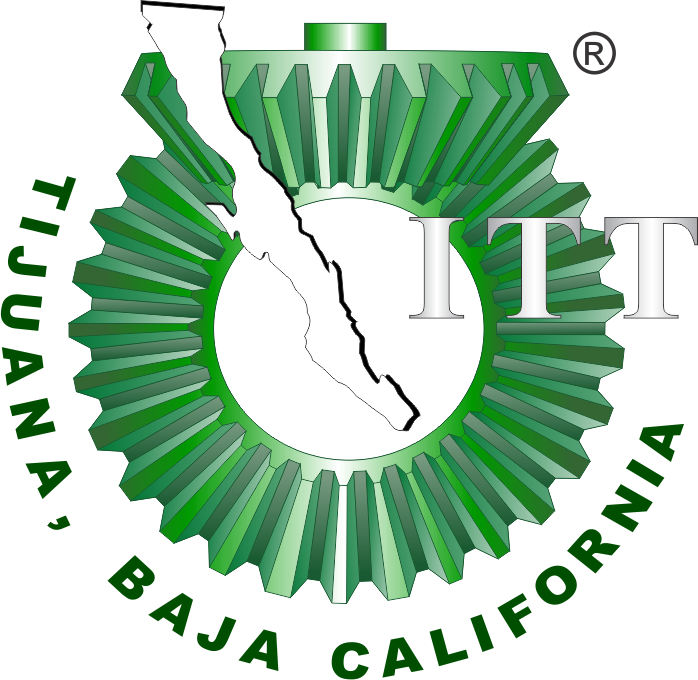

# Práctica dos: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

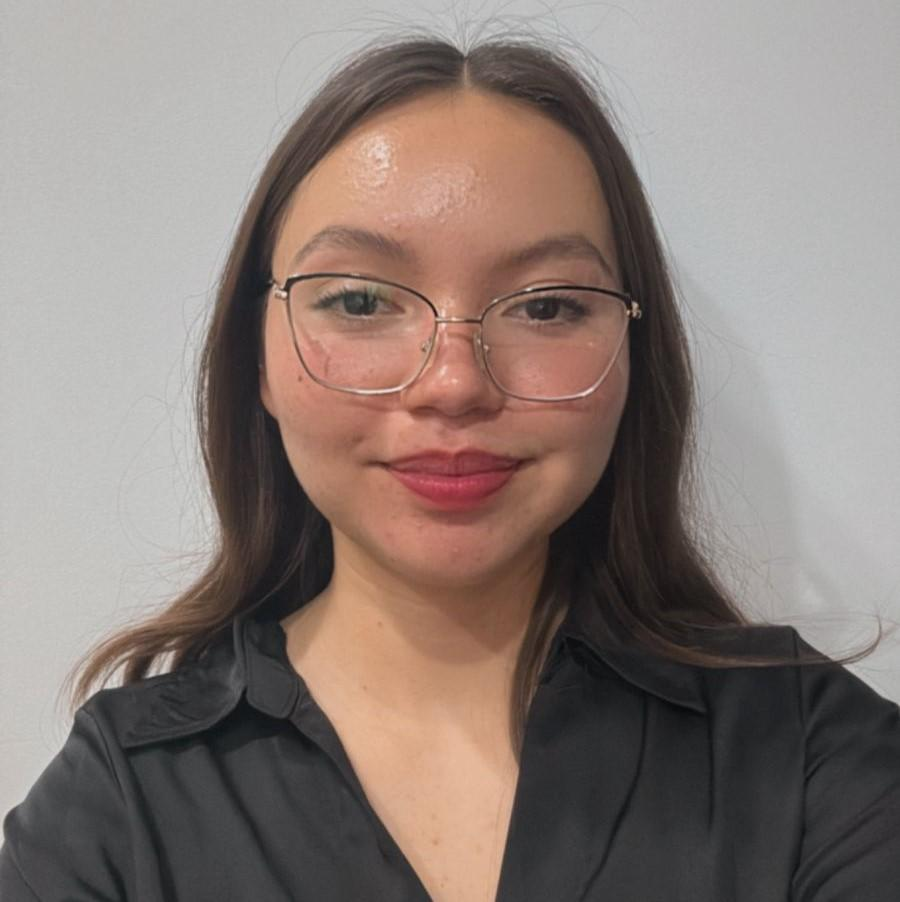

Nombre del alumno: **Karla Emilia Silva Pérez**

Número de control: **22211767**

Correo institucional: **l22211767@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

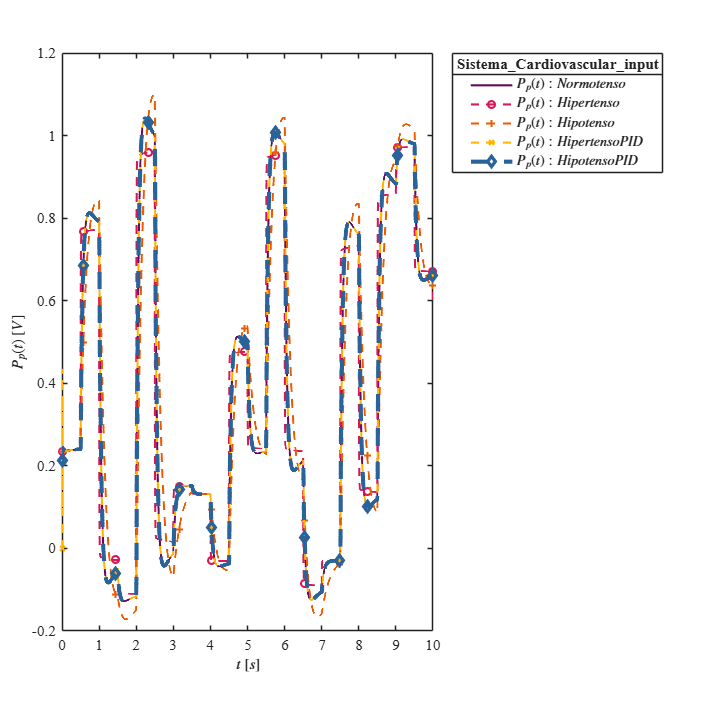

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistemaB';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
set_param('sistemaB/Ppa(t)','Minimum','-0.2');
set_param('sistemaB/Ppa(t)','Maximum','1');
set_param('sistemaB/Ppa(t)','Seed','106');
set_param('sistemaB/Ppa(t)','SampleTime','0.5');
x = sim(file, parameters);
writematrix(x.Ppa,'signal.xlsx')
Signal = 'Sistema_Cardiovascular';
plotsignals(x.tout,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,Signal)

## Respuesta a las 3 funciones

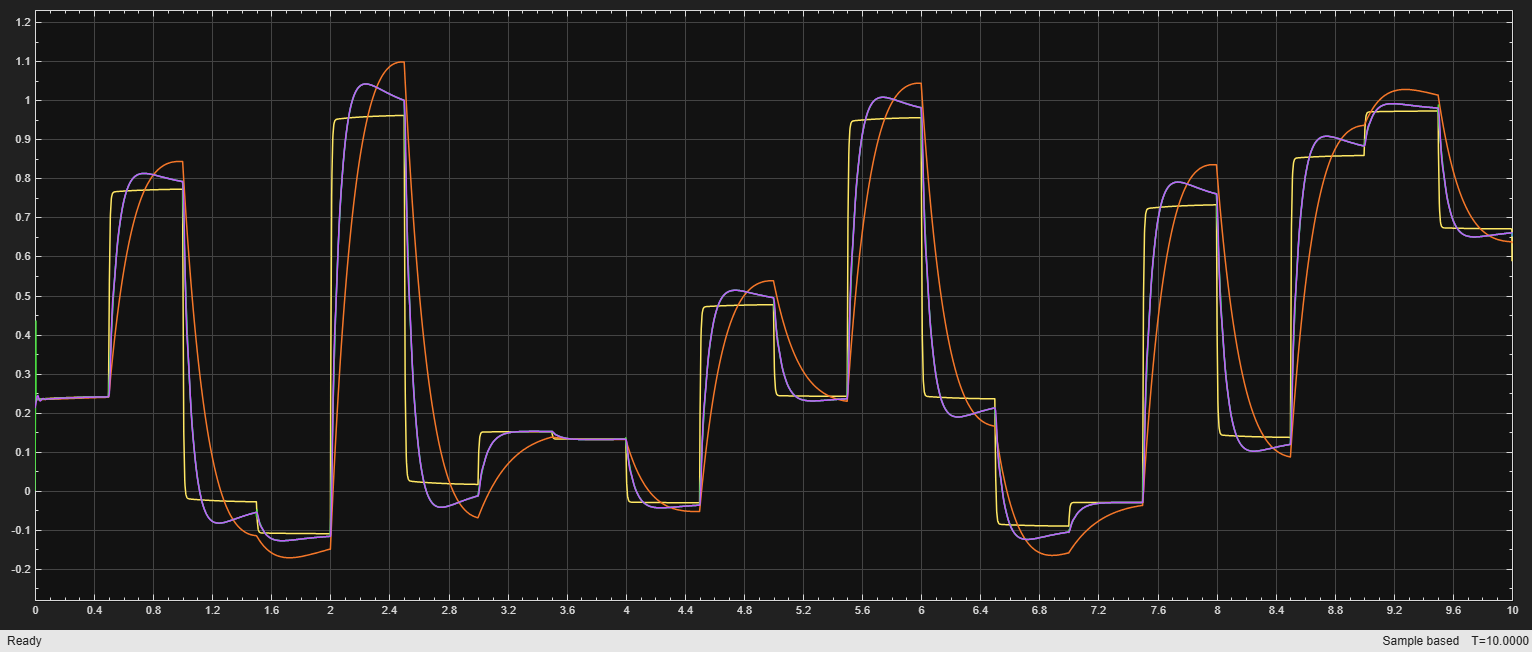

file = 'sistemaB';
open_system(file);
set_param('sistemaB/Ppa(t)','Minimum','-0.2');
set_param('sistemaB/Ppa(t)','Maximum','1');
set_param('sistemaB/Ppa(t)','Seed','106');
set_param('sistemaB/Ppa(t)','SampleTime','0.5');
x1 = sim(file, parameters);

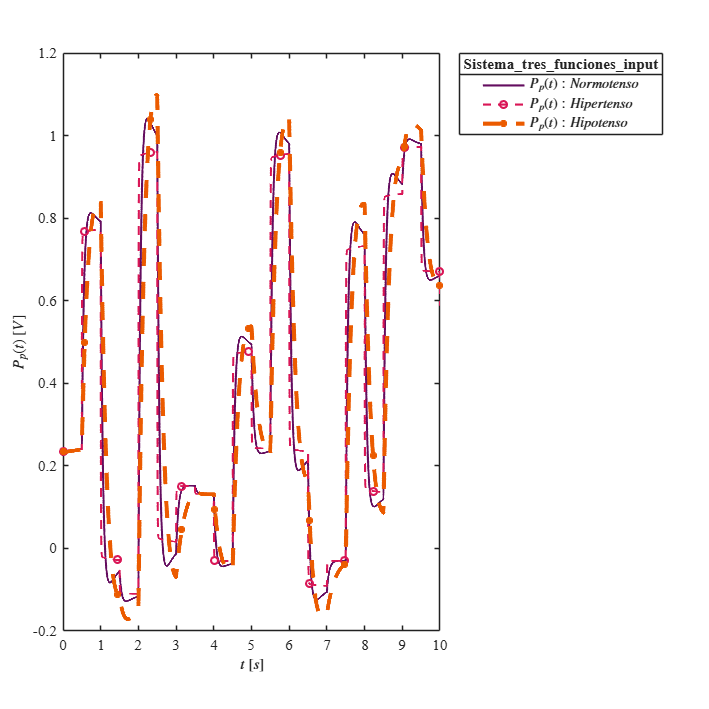

Signal = 'Sistema_tres_funciones';
plotsignals(x1.tout,x1.Pp0,x1.Pp1,x1.Pp2,[],[],Signal)

## Funcion: Respuesta a las señales

function plotsignals(tout,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
set(figure(), 'Color', 'w')
set(gcf,'units','centimeters','position',[1,1,18,18])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [100,13,95;
217,22,86;
235,91,0;
255,178,0;
42,98,154;
247,82,112]/255;

colororder(mycolors)

% p=(plot(tout,Pp0,'-',tout,Pp1,'--O',tout,Pp2,'--+',tout,Pp3,'--X',tout,Pp4,'--d',...
% 'LineWidth', 1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(tout)));

% L = legend('$P_{p}(t):Normotenso$', '$P_{p}(t):Hipertenso$','$P_{p}(t):Hipotenso$','$P_{p}(t):Hipertenso PID$','$P_{p}(t):Hipotenso PID$');
% set(p(5),'LineWidth',3);

% set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');

if Signal == "Sistema_Cardiovascular"
    p=(plot(tout,Pp0,'-',tout,Pp1,'--O',tout,Pp2,'--+',tout,Pp3,'--X',tout,Pp4,'--d',...
'LineWidth', 1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(tout)));
    set(p(5),'LineWidth',3);
    L = legend('$P_{p}(t):Normotenso$', '$P_{p}(t):Hipertenso$','$P_{p}(t):Hipotenso$','$P_{p}(t):Hipertenso PID$','$P_{p}(t):Hipotenso PID$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');

elseif Signal == "Sistema_tres_funciones"
    p=(plot(tout,Pp0,'-',tout,Pp1,'--O',tout,Pp2,'--+',...
'LineWidth', 1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(tout)));
    set(p(3),'LineWidth',3);
    L = legend('$P_{p}(t):Normotenso$', '$P_{p}(t):Hipertenso$','$P_{p}(t):Hipotenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
end

    title(L,[Signal, '_input'], 'FontSize',11)

xlabel('$t$ $[s]$','Interpreter','Latex','Fontsize',11)
ylabel('$P_p(t)$ $[V]$','Interpreter','Latex','FontSize',11)

xlim([0,10]); xticks (0:1:10);

if Signal == "Step" || Signal== "Impulse"
    ylim([0,1.2]); yticks (0:0.1:1.2);
elseif Signal == "Ramp"
ylim([-0.1,1.1]); yticks (-0.1:0.1:1.1);
elseif Signal == "Sin"
ylim([-1.2,1.2]); yticks (-1.2:0.2:2);
end

exportgraphics (gcf,[Signal, '.pdf'],'ContentType','vector')
exportgraphics (gcf,[Signal, '.png'],'ContentType','vector')
end